# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : https://github.com/BaeYunjae?tab=repositories

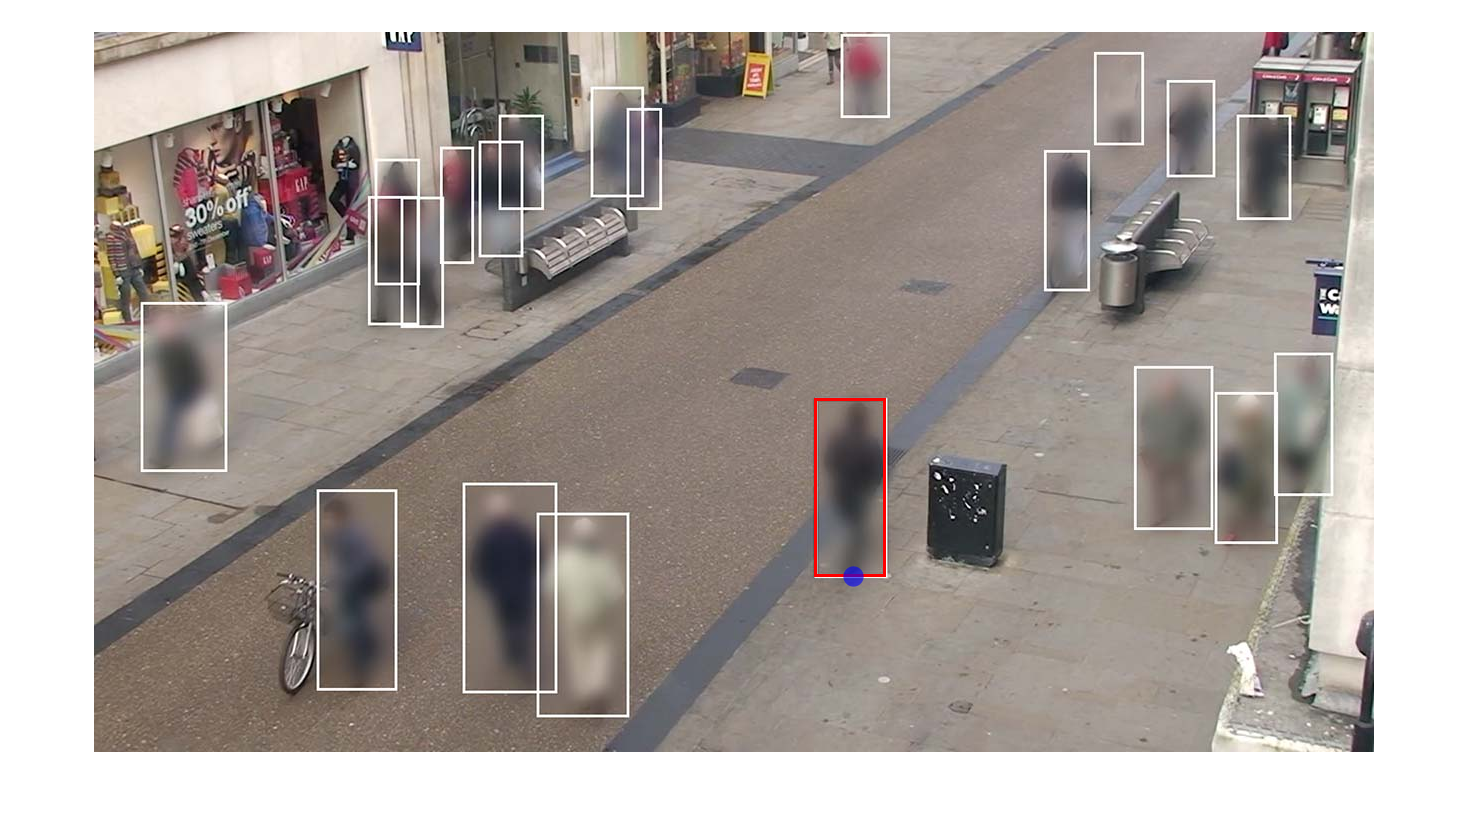

% image 정보 불러오기
img = imread("background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

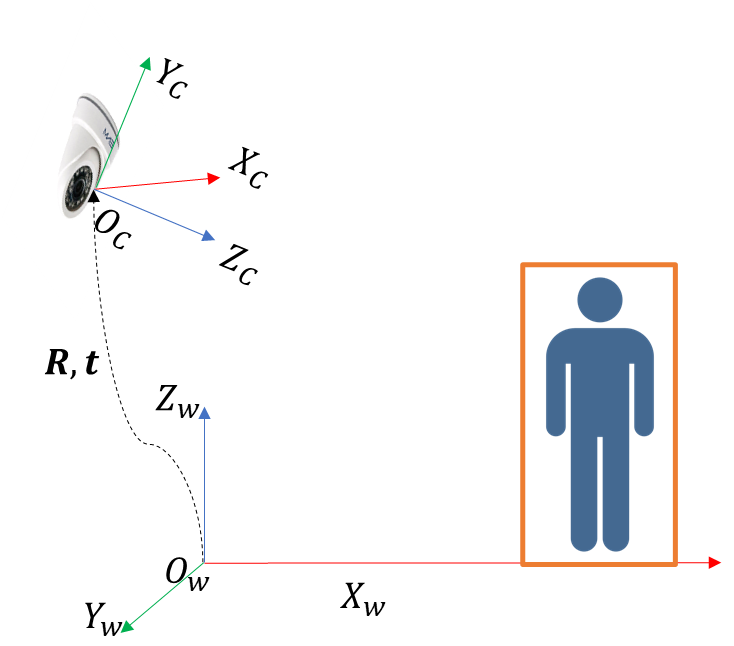

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = pi/2 - pi/6;  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도
% 위치
tx = 0;
ty = -5;
tz = 0.2

tz = 0.2000

% Camera Matrix?
K = [fx 0 cx; 0 fy cy; 0 0 1]

K =         1000           0         640
           0        1000         480
           0           0           1


% Rotation Matrix?
R = Rz(theta_z) * Ry(theta_y) * Rx(theta_x)

R =     0.0000   -0.5000    0.8660
    0.0000   -0.8660   -0.5000
    1.0000    0.0000    0.0000


% Translation Matrix?
t = [tx; ty; tz]

t =          0
   -5.0000
    0.2000


% World Coordinate 좌표 값?
W = inv([inv(K)*[u; v; 1] , -R(:,1) , -R(:,2)]) * t 

W =    35.0027
   34.8027
   -8.4006


Xw = W(2,1)

Xw = 34.8027

Yw = W(3,1)

Yw = -8.4006

if length(W) == 4
    Zw = W(4,1)
else 
    Zw = 0
end;

Zw = 0


function rot_x = Rx(rx)
    rot_x = [1 0 0; 0 cos(rx) -sin(rx); 0 sin(rx) cos(rx)];    
end
function rot_y = Ry(ry)
    rot_y = [cos(ry) 0 sin(ry); 0 1 0; -sin(ry) 0 cos(ry)];
end
function rot_z = Rz(rz)
    rot_z = [cos(rz) -sin(rz) 0; sin(rz) cos(rz) 0; 0 0 1];
end